clear all;
close all;
clc;

% TODO: add constants from previous sections
k_phi = 0.968;
Vf = 327.6;
If = 0.48;
Ra = 1.63;
Rf = 658;

% Calculate - Model
Tf_model = 0.7;
Ts_model = -7:0.01:7;
Va_model = 150;

% TODO: insert equations to calculate powers and efficiency
Td_model = Ts_model+Tf_model;
Ia_model = Td_model / k_phi;
E_model = Va_model - Ia_model*Ra;
omega_m_model = E_model/k_phi;
Ps_model = Ts_model .* omega_m_model;
n_model = omega_m_model/(2 * pi);
eff_motor_model = (Ts_model > 0).*(Td_model > 0).*Ps_model./((Va_model.*Ia_model)+(If.^2*Rf));
% eff_motor(eff_motor == 0) = NaN;

eff_gen_model = (Ts_model < 0).*(Td_model < 0).*(abs(Va_model.*Ia_model))./(abs(Ps_model)+(If.*Vf));
% eff_gen(eff_gen == 0) = NaN;
eff_real = eff_motor_model + eff_gen_model;

% Calculate - Actual

Ns = 43;
s = 3; % time step

load('Measurement_Data/Measurement_2023_12_6_17_24.mat');
for i = 1:1:Ns
   Ia_DCM_filtered(1, i) = mean(Ia_DCM(1600*i*s-2000-1:1600*i*s-1));
   Va_DCM_filtered(1, i) = mean(Va_DCM(1600*i*s-2000-1:1600*i*s-1));
   Ia_ACM_filtered(1, i) = mean(Ia_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   Van_ACM_filtered(1, i) = mean(Van_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   PF_ACM_filtered(1, i) = mean(PF_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   n_filtered(1, i) = mean(n(1600*i*s-2000-1:1600*i*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_15_44.mat');
for i = 1:1:Ns
   Ia_DCM_filtered(2, i) = mean(Ia_DCM(1600*i*s-2000-1:1600*i*s-1));
   Va_DCM_filtered(2, i) = mean(Va_DCM(1600*i*s-2000-1:1600*i*s-1));
   Ia_ACM_filtered(2, i) = mean(Ia_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   Van_ACM_filtered(2, i) = mean(Van_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   PF_ACM_filtered(2, i) = mean(PF_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   n_filtered(2, i) = mean(n(1600*i*s-2000-1:1600*i*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_15_57.mat');
for i = 1:1:Ns
   Ia_DCM_filtered(3, i) = mean(Ia_DCM(1600*i*s-2000-1:1600*i*s-1));
   Va_DCM_filtered(3, i) = mean(Va_DCM(1600*i*s-2000-1:1600*i*s-1));
   Ia_ACM_filtered(3, i) = mean(Ia_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   Van_ACM_filtered(3, i) = mean(Van_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   PF_ACM_filtered(3, i) = mean(PF_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   n_filtered(3, i) = mean(n(1600*i*s-2000-1:1600*i*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_16_1.mat');
for i = 1:1:Ns
   Ia_DCM_filtered(4, i) = mean(Ia_DCM(1600*i*s-2000-1:1600*i*s-1));
   Va_DCM_filtered(4, i) = mean(Va_DCM(1600*i*s-2000-1:1600*i*s-1));
   Ia_ACM_filtered(4, i) = mean(Ia_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   Van_ACM_filtered(4, i) = mean(Van_rms_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   PF_ACM_filtered(4, i) = mean(PF_ACM(1600*i*s-2000-1:1600*i*s-1)); 
   n_filtered(4, i) = mean(n(1600*i*s-2000-1:1600*i*s-1));
end

% calculate omega_m continuous
omega_m_real = n_filtered * 2*pi;

% continuous tfw_DCM
Tf_real = 0.8 * ((0.001638 * omega_m_real) + 0.4942);

Td_real = k_phi*Ia_DCM_filtered;
Ts_real = Td_real-Tf_real;
Ps_real = Ts_real .* omega_m_real;

% combined eff of motor/gen use for loop - for overview
eff_motor_real = (Ts_real > 0).*(Td_real > 0).*Ps_real./((Va_DCM_filtered.*Ia_DCM_filtered)+(If.*Vf));
% eff_motor(eff_motor == 0) = NaN;

eff_gen_real = (Ts_real < 0).*(Td_real < 0).*(abs(Va_DCM_filtered.*Ia_DCM_filtered))./(abs(Ps_real)+(If.*Vf));
% eff_gen(eff_gen == 0) = NaN;

eff_real = eff_motor_real + eff_gen_real;

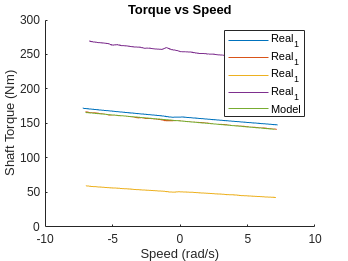

figure;
hold on;
for i=1:4
    plot(Ts_real(i,:), omega_m_real(i,:));
end
plot(Ts_model, omega_m_model);
legend('Real_1', 'Real_1', 'Real_1', 'Real_1', 'Model');
title('Torque vs Speed');
xlabel('Speed (rad/s)');
ylabel('Shaft Torque (Nm)');